A=dec2base(0:3^5-1, 3) - '0'+ 1;
A

A =      1     1     1     1     1
     1     1     1     1     2
     1     1     1     1     3
     1     1     1     2     1
     1     1     1     2     2
     1     1     1     2     3
     1     1     1     3     1
     1     1     1     3     2
     1     1     1     3     3
     1     1     2     1     1


ii=sum(A,2)

ii =      5
     6
     7
     6
     7
     8
     7
     8
     9
     6


l = find(ii>=5&ii<10); 
h = ii(l)*475;h

h =         2375
        2850
        3325
        2850
        3325
        3800
        3325
        3800
        4275
        2850


s = find(ii>9); 
g = ii(s)*450;g

g =         4500
        4500
        4500
        4950
        4500
        4500
        4500
        4950
        4500
        4500


t=[h; g]

t =         2375
        2850
        3325
        2850
        3325
        3800
        3325
        3800
        4275
        2850


S = sort(ii,'ascend')

S =      5
     6
     6
     6
     6
     6
     7
     7
     7
     7


total_cost = sort(t,'ascend')

total_cost =         2375
        2850
        2850
        2850
        2850
        2850
        3325
        3325
        3325
        3325


x1 = A(:,1);x2 = A(:,2);x3 = A(:,3);x4 = A(:,4);x5 = A(:,5)

x5 =      1
     2
     3
     1
     2
     3
     1
     2
     3
     1


B1 = [x1 2.*x2 5.*x3.*x2.*x2 3.*x4 10.*x5]

B1 =      1     2     5     3    10
     1     2     5     3    20
     1     2     5     3    30
     1     2     5     6    10
     1     2     5     6    20
     1     2     5     6    30
     1     2     5     9    10
     1     2     5     9    20
     1     2     5     9    30
     1     2    10     3    10


total_benefitB1 = sum(B1,2)

total_benefitB1 =     21
    31
    41
    24
    34
    44
    27
    37
    47
    26


B2 = [-x1 2.*x2.*x2.*x2 2.*x3.*x2.*x2 3./(1+x4) 5./(1+x5)]

B2 =    -1.0000    2.0000    2.0000    1.5000    2.5000
   -1.0000    2.0000    2.0000    1.5000    1.6667
   -1.0000    2.0000    2.0000    1.5000    1.2500
   -1.0000    2.0000    2.0000    1.0000    2.5000
   -1.0000    2.0000    2.0000    1.0000    1.6667
   -1.0000    2.0000    2.0000    1.0000    1.2500
   -1.0000    2.0000    2.0000    0.7500    2.5000
   -1.0000    2.0000    2.0000    0.7500    1.6667
   -1.0000    2.0000    2.0000    0.7500    1.2500
   -1.0000    2.0000    4.0000    1.5000    2.5000


total_benefitB2 = sum(B2,2)

total_benefitB2 =     7.0000
    6.1667
    5.7500
    6.5000
    5.6667
    5.2500
    6.2500
    5.4167
    5.0000
    9.0000


total_cost_norm = [total_cost./max(total_cost)]

total_cost_norm =     0.3519
    0.4222
    0.4222
    0.4222
    0.4222
    0.4222
    0.4926
    0.4926
    0.4926
    0.4926


total_benB1_norm = [total_benefitB1./max(total_benefitB1)]

total_benB1_norm =     0.1148
    0.1694
    0.2240
    0.1311
    0.1858
    0.2404
    0.1475
    0.2022
    0.2568
    0.1421


total_benB2_norm = [total_benefitB2./max(total_benefitB2)]

total_benB2_norm =     0.0631
    0.0556
    0.0518
    0.0586
    0.0511
    0.0473
    0.0563
    0.0488
    0.0450
    0.0811


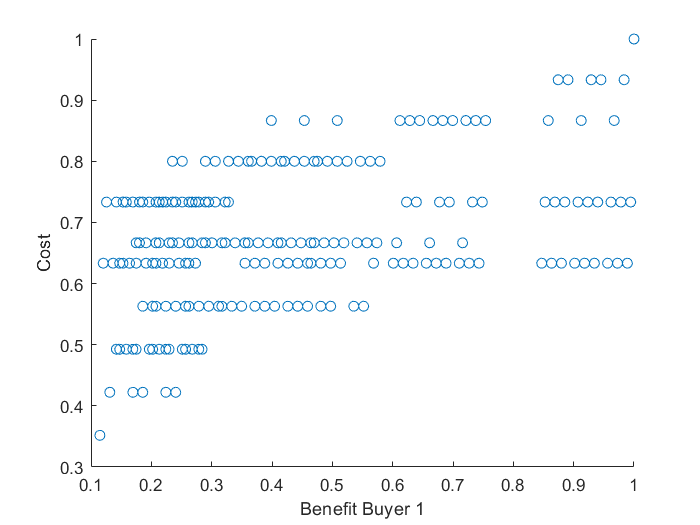

scatter(total_benB1_norm,total_cost_norm)

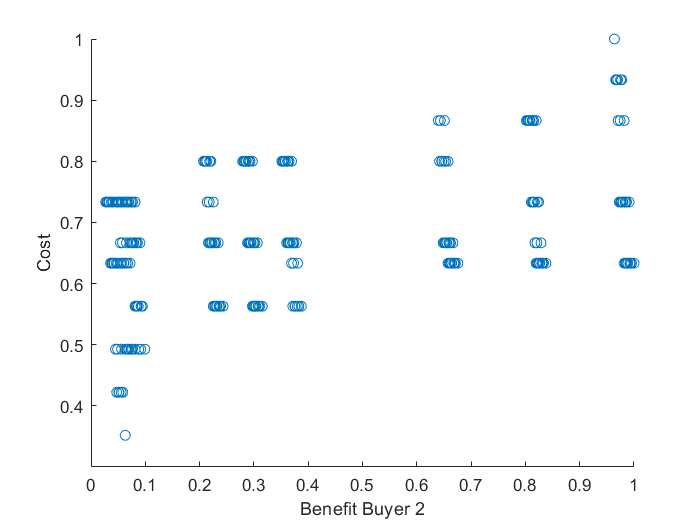

scatter(total_benB2_norm,total_cost_norm)